# Pole Vault - 2024 Olympics update

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_08_07_pole_vault/2024_08_07_pole_vault.prj)

In 2016, we published [this blog post](https://blogs.mathworks.com/simulink/2016/08/19/olympic-2016-pole-vault) simulating a [pole vault jump](https://en.wikipedia.org/wiki/Pole_vault_at_the_Olympics). I decided to revisit this topic and demonstrate how I would simulate this using the latest features in Simulink.

## Pole Vault Model

Here is an illustration of what a pole vault jump looks like:

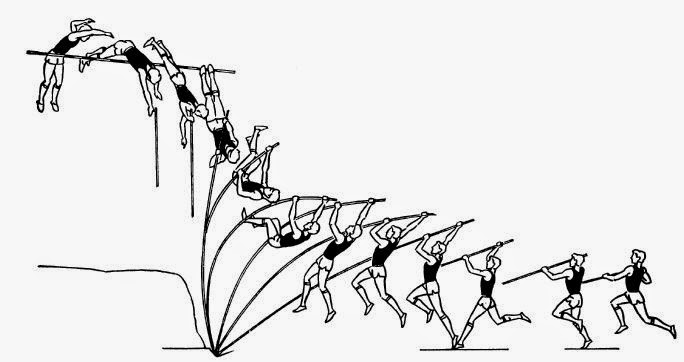

*Credit: *[*Rethinking Athletics: Pole vault: a sprinkle of physics*](https://rethinkingathletics.blogspot.com/2014/09/pole-vault-sprinkle-of-physics.html)

To simulate this event, we can divide the jump in three phases:

- **Approach:** During this phase the athlete tries to maximize his speed along the runway to achieve maximum kinetic energy

- **Take off and swing up: **The athlete positions the pole into the “box” to convert the kinetic energy into stored potential energy in the pole and swing up.

- **Fly away:** The vaulter releases the pole and falls back on the mat under the influence of gravity

In 2016, the way to model that was using a series of 3 [If Action Subsystems](https://www.mathworks.com/help/releases/R2024a/simulink/slref/ifactionsubsystem.html). When switching from one phase to the next, we would transfer the states from one Subsystem to the next using the [Integrator](https://www.mathworks.com/help/releases/R2024a/simulink/slref/integrator.html) block state port and [GoTo](https://www.mathworks.com/help/releases/R2024a/simulink/slref/goto.html) and [From](https://www.mathworks.com/help/releases/R2024a/simulink/slref/from.html) blocks.

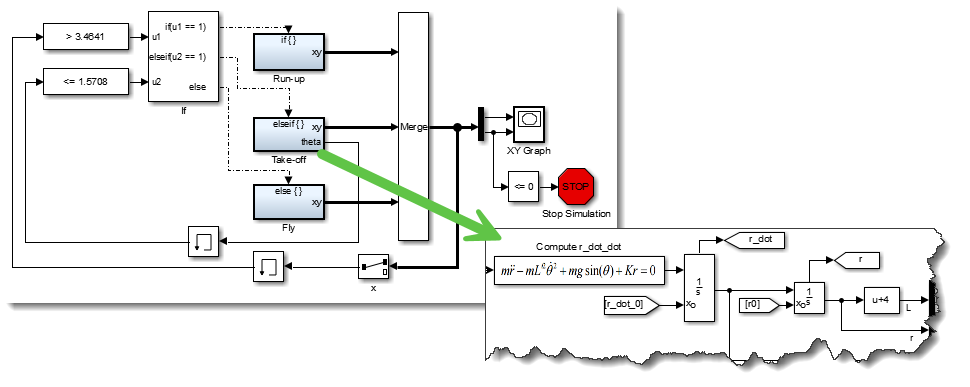

This semantic and it had multiple imitations. Let's see my preferred way to implement the same equations in MATLAB R2024a.

## Simulink States inside Stateflow

Here is what my new model looks like.

mdl = "poleVaultSim";
open_system(mdl);

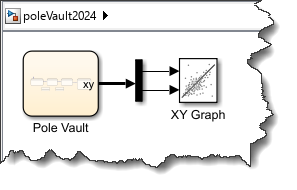

Yes, this is correct, only one [Stateflow Chart](https://www.mathworks.com/help/releases/R2024a/stateflow/index.html). Don't be fooled, the Simulink blocks are inside!

The Stateflow chart is made of 4 [Simulink States](https://www.mathworks.com/help/releases/R2024a/stateflow/simulink-based-states.html) and 2 [Simulink functions](https://www.mathworks.com/help/releases/R2024a/stateflow/simulink-functions.html).

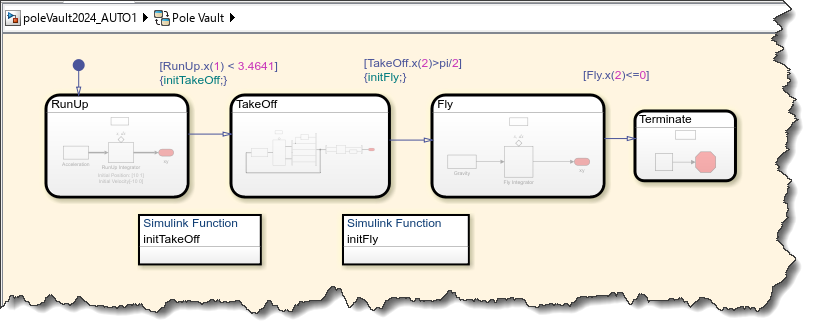

During the Run Up phase, I integrate the motion of the athlete running at a constant speed. Compared to the 2016 implementation, I am able to use the [Second Order Integrator](https://www.mathworks.com/help/releases/R2024a/simulink/slref/secondorderintegrator.html) instead of two [Integrator](https://www.mathworks.com/help/releases/R2024a/simulink/slref/integrator.html) blocks, because the Second Order Integrator does not have a state port option.

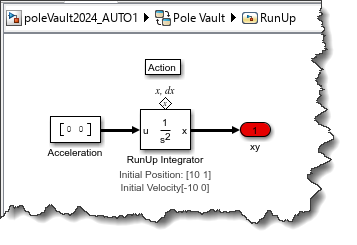

During the Take Off, the motion of the athlete is computed in polar coordinate. This makes it simpler to solve the equations for the bending of the pole.

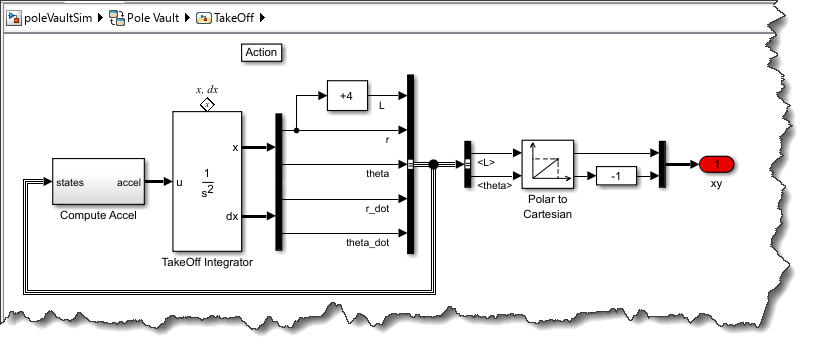

The important part to notice is what happens in the Simulink Functions. Using [State Reader](https://www.mathworks.com/help/releases/R2024a/simulink/slref/statereader.html) blocks, I can access the states of the Integrator blocks in the previous phase and compute the initial states of the next phase. I can then use [State Writer](https://www.mathworks.com/help/releases/R2024a/simulink/slref/statewriter.html) blocks to initialize the Integrator blocks in the next phase.

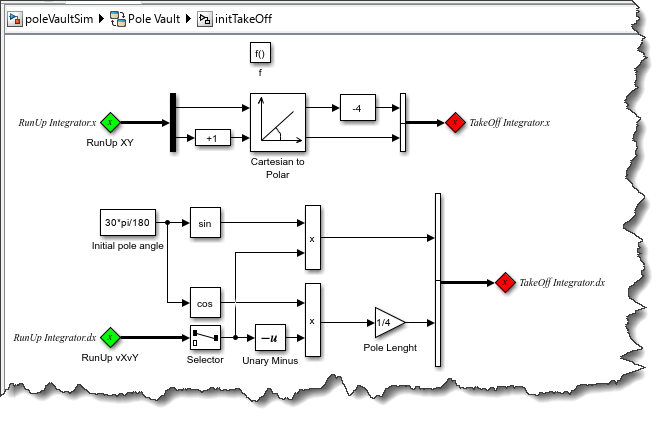

When simulating the model, we can follow the evolution of the simulation through the [Stateflow animation](https://www.mathworks.com/help/releases/R2024a/stateflow/ug/animate-stateflow-charts.html) and the newly revamped XY Graph block, which is just a pre-configured instance of the [Record block](https://www.mathworks.com/help/releases/R2024a/simulink/slref/record.html).

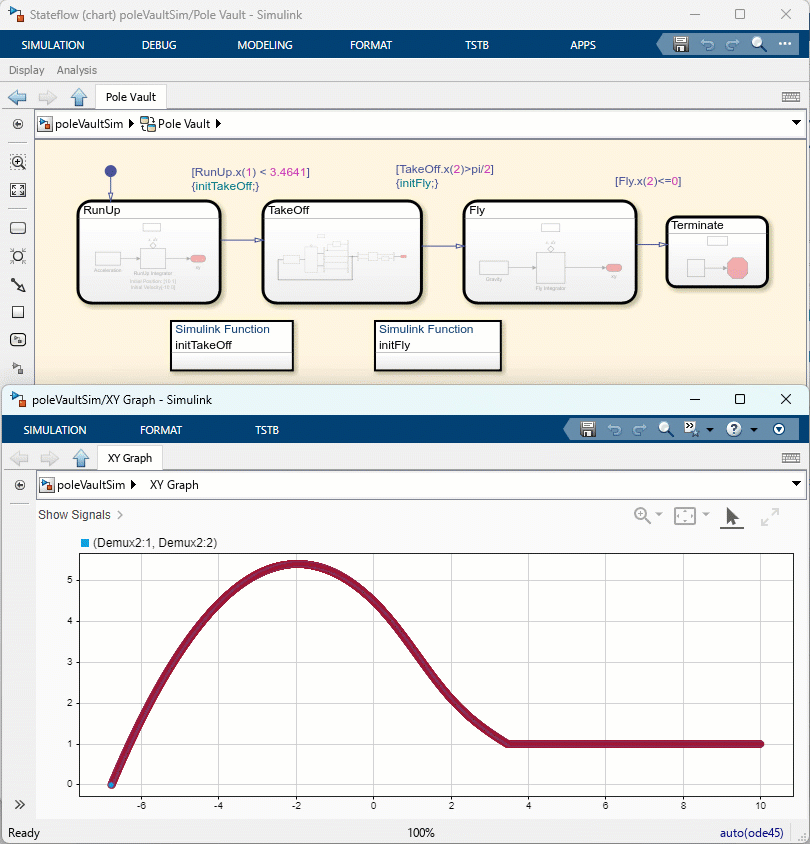

Let's simulate from the command-line.

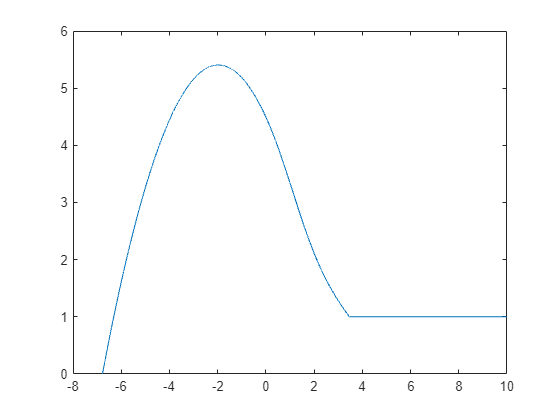

out = sim(mdl);
figure
plot(out.logsout.get('x').Values.Data,out.logsout.get('y').Values.Data)

## Now it's your turn

Don't miss the actual pole vault competition at the Paris Olympic:

- [Men's pole vault schedule](https://olympics.com/en/paris-2024/schedule/athletics/men-s-pole-vault?day=undefined)

- [Women's pole vault schedule](https://olympics.com/en/paris-2024/schedule/athletics/women-s-pole-vault?day=undefined)

How would you simulate the pole vault competition? Let us know in the comments below.